clear; clc; close all;

%% Parameter definieren (Quelle: Wikipedia)


G = 6.67430e-11;       % Gravitationskonstante 
M_sonne = 1.9884e30;   % Masse der Sonne in kg

abstand_erde_sonne=149.6*10^9;%[m]
radius_erde=6371*10^3;%[m]

% Erde
pos_erde = [abstand_erde_sonne, 0, 0];
T_Erde = 365.25*24*3600;    %[s]% 365.25=Umlaufzeit in Tagen
R_Erde = pos_erde(1);
M_erde  = 5.9722e24;   % Masse der Erde in kg

% Mars
pos_mars = [-227.9e9, 0, 0];
T_Mars = 687*24*3600;       %[s]% 687=Umlaufzeit in Tagen ca.
R_Mars = norm(pos_mars(1));
M_mars  = 6.39e23;

%% 2. Berechnung der Winkelgeschwindigkeiten
% omega = 2 * pi / T
w_Erde = 2 * pi / T_Erde;
w_Mars = 2 * pi / T_Mars;

## Aufgabe 1: Plot: Modell des Sonnensystems

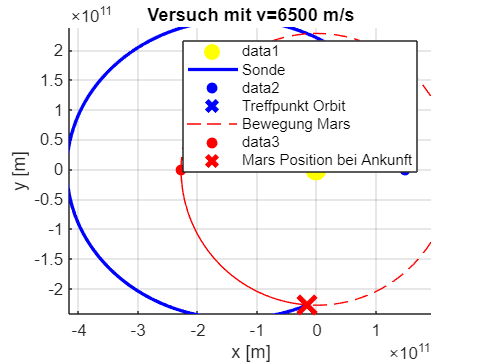

%Zeitvektor erstellen
% Wir simulieren 2 Jahre (ca. 730 Tage)
t = 0:(1*24*3600):(730*24*3600); 

%% Berechnung der Bahnkurven (Trajektorien)
% Erde
x_Erde = R_Erde * cos(w_Erde * t);
y_Erde = R_Erde * sin(w_Erde * t);

% Mars
x_Mars = R_Mars * cos(w_Mars * t);
y_Mars = R_Mars * sin(w_Mars * t);

%% 5. Visualisierung
figure('Name', 'Sonnensystem Modell: Erde und Mars');
hold on; grid on; axis equal;

% Sonne im Ursprung
plot(0, 0, 'yo', 'MarkerSize', 15, 'MarkerFaceColor', 'yellow', 'DisplayName', 'Sonne');

% Bahn und Position der Erde
plot(x_Erde, y_Erde, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Erde');
plot(x_Erde(end), y_Erde(end), 'bo', 'MarkerFaceColor', 'blue', 'DisplayName', 'Erde (aktuell)');

% Bahn und Position des Mars
plot(x_Mars, y_Mars, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Mars');
plot(x_Mars(1), y_Mars(1), 'ro', 'MarkerFaceColor', 'red', 'DisplayName', 'Mars (aktuell)');

% Beschriftung
xlabel('Distanz in x [km]');
ylabel('Distanz in y [km]');
title('Modell des Sonnensystems (Erde & Mars)');
legend('Location', 'northeastoutside');

hold off;

% Parameter für die ode Funktion
tspan=[0 365*24*3600];

r0=[abstand_erde_sonne+radius_erde; 0; 0];
v0=[0;w_Erde*abstand_erde_sonne+15*10^3;0];
u0=[r0;v0];

## Nur mit Einfluss vom Gravitationsfeld Sonne

input_fuer_ode_sun=@(t,u) DGL_Sonne(t, u, G, M_sonne);
%das muss so gemacht werden, da ode45 nur zwei eingabewerte akzeptiert(t&u)
[t_erg_sun, u_erg_sun]=ode45(input_fuer_ode_sun,tspan,u0);
%t muss hier nur wegen syntaxvorgabe von ode45
plot(u_erg_sun(:,1), u_erg_sun(:,2))

## Mit Einfluss von Sonne, Erde und Mars

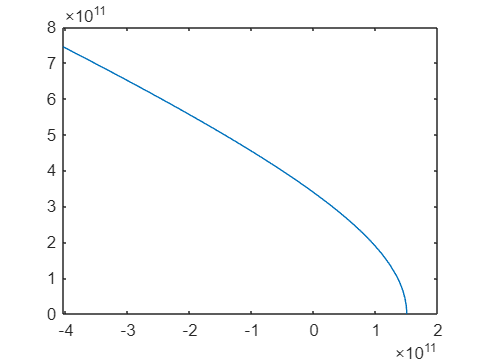

input_fuer_ode_sonnensystem=@(t,u) DGL_Sonnensystem(t, u, G, M_sonne, M_erde, M_mars, R_Erde, R_Mars, w_Erde, w_Mars);
%das muss so gemacht werden, da ode45 nur zwei eingabewerte akzeptiert(t&u)
[t_erg_so_sys, u_erg_so_sys]=ode45(input_fuer_ode_sonnensystem,tspan,u0);
%t muss hier nur wegen syntaxvorgabe von ode45
plot(u_erg_so_sys(:,1), u_erg_so_sys(:,2))

## Finden der Geschwindigkeit, um Mars zu treffen

% Start-Schätzung (Rate mal: z.B. 3 km/s zusätzlich)
v_guess = 6500; 

% Wrapper für fminsearch definieren
% Wir fixieren alle Parameter, die fminsearch nicht ändern darf,
% sodass nur 'v' variabel bleibt.
optimierungs_func = @(v) ziel_funktion_mars(v, G, M_sonne, R_Erde, R_Mars, w_Erde, w_Mars, pos_erde, pos_mars);


[v_opt, fehler_min] = fminsearch(optimierungs_func, v_guess, options_fmin);

 
 Iteration   Func-count         f(x)         Procedure
     0            1      5.54147e+10         
     1            2      5.54147e+10         initial simplex
     2            4      2.06029e+10         contract outside
     3            6      1.68095e+10         contract inside
     4            8       2.0589e+09         contract inside
     5           10       2.0589e+09         contract inside
     6           12       2.0589e+09         contract inside
     7           14      2.82396e+08         contract inside
     8           16      2.82396e+08         contract inside
     9           18      2.82396e+08         contract inside
    10           20      1.05425e+07         contract inside
    11           22      1.05425e+07         contract inside
    12           24      1.05425e+07         contract inside
    13           26      1.05425e+07         contract inside
    14           28      7.76379e+06         contract inside
    15           30      1.38942e+06      


fprintf('Optimale Zusatzgeschwindigkeit: %.2f m/s\n', v_opt);

Optimale Zusatzgeschwindigkeit: 6382.59 m/s


fprintf('Restlicher Abstand zum Mars: %.2f km\n', fehler_min/1000);

Restlicher Abstand zum Mars: 0.00 km



% Manuelle Simulation für den Plot
r0 = pos_erde';
v_erde_tangential = w_Erde * R_Erde;
v0 = [0; v_erde_tangential + v_opt; 0];
u0 = [r0; v0];

options = odeset('Events', @(t,u) event_marsbahn(t, u, R_Mars), 'RelTol', 1e-6);
tspan = [0 4*365*24*3600]; % Lange Laufzeit

[t_out, u_out, te, ue, ie] = ode45(@(t,u) DGL_Sonne(t, u, G, M_sonne), tspan, u0, options);

fprintf("Die Sonde braucht %.2f Tage um den Mars zu treffen", te/(24*3600));

Die Sonde braucht 851.37 Tage um den Mars zu treffen

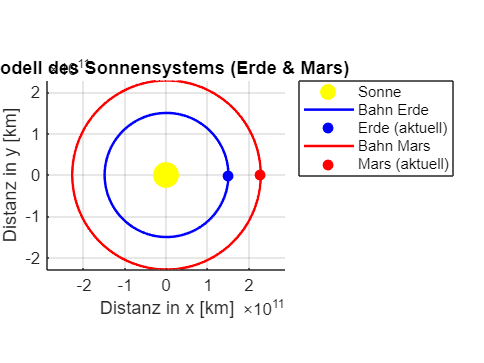


% Mars-Position über die Zeit berechnen
x_mars_plot = [];
y_mars_plot = [];
phi_mars_start = atan2(pos_mars(2), pos_mars(1));

for k = 1:length(t_out)
    phi_now = phi_mars_start + w_Mars * t_out(k);
    x_mars_plot(k) = R_Mars * cos(phi_now);
    y_mars_plot(k) = R_Mars * sin(phi_now);
end

% Plotten
figure('Name', 'Fehler-Analyse');
hold on; axis equal; grid on;

% Sonne
plot(0,0, 'yo', 'MarkerFaceColor', 'y', 'MarkerSize', 12);

% Flugbahn Sonde
plot(u_out(:,1), u_out(:,2), 'b-', 'LineWidth', 2, 'DisplayName', 'Sonde');
% Startpunkt Sonde
plot(u_out(1,1), u_out(1,2), 'bo', 'MarkerFaceColor', 'b');
% Endpunkt Sonde (wo sie die Marsbahn kreuzt)
plot(ue(end,1), ue(end,2), 'bx', 'MarkerSize', 15, 'LineWidth', 3, 'DisplayName', 'Treffpunkt Orbit');

% Flugbahn Mars (während die Sonde fliegt)
plot(x_mars_plot, y_mars_plot, 'r--', 'DisplayName', 'Bewegung Mars');
% Startpunkt Mars
plot(x_mars_plot(1), y_mars_plot(1), 'ro', 'MarkerFaceColor', 'r');
% Endpunkt Mars (wo er ist, wenn die Sonde ankommt)
end_idx = length(t_out);
plot(x_mars_plot(end_idx), y_mars_plot(end_idx), 'rx', 'MarkerSize', 15, 'LineWidth', 3, 'DisplayName', 'Mars Position bei Ankunft');




function abstand_fehler = ziel_funktion_mars(v_start_guess, G, M_sonne, R_Erde, R_Mars, w_Erde, w_Mars, start_pos_erde, start_pos_mars)
    
    % 1. Startbedingungen
    r0 = start_pos_erde'; 
    v_erde_tangential = w_Erde * R_Erde;
    v0 = [0; v_erde_tangential + v_start_guess; 0];
    u0 = [r0; v0];
    
    % 2. Simulation
    % WICHTIG: Direction = 1 (von innen nach außen) ist korrekt.
    options = odeset('Events', @(t,u) event_marsbahn(t, u, R_Mars), 'RelTol', 1e-6, 'AbsTol', 1e-8);
    tspan = [0 3*365*24*3600]; % Zeitrahmen lang genug wählen
    
    [t_out, u_out, te, ue, ie] = ode45(@(t,u) DGL_Sonne(t, u, G, M_sonne), tspan, u0, options);
    
    % --- HIER IST DIE ÄNDERUNG ---
    
    % Fall A: Die Sonde war zu langsam und hat die Marsbahn NIE erreicht
    if isempty(te)
        % Wir berechnen, wie weit die Sonde maximal gekommen ist (Aphel)
        abstand_sonne = sqrt(u_out(:,1).^2 + u_out(:,2).^2 + u_out(:,3).^2);
        max_erreichte_distanz = max(abstand_sonne);
        
        % Der Fehler ist: Wie viel fehlt noch bis zum Mars-Radius?
        missing_distance = R_Mars - max_erreichte_distanz;
        
        % Wir addieren eine "Strafe" (z.B. 1 Milliarde km), damit dieser Fehler 
        % immer größer ist als ein echter Treffer, aber trotzdem kleiner wird, 
        % je mehr Gas wir geben.
        penalty_base = 1e11; 
        abstand_fehler = penalty_base + missing_distance;
        
        return; 
    end
    
    % Fall B: Die Sonde hat die Marsbahn gekreuzt (Event hat ausgelöst)
    % Jetzt machen wir die normale Berechnung wie vorher
    
    % Zeit beim Kreuzen
    t_kreuzung = te(end); % Falls mehrmals, nimm das letzte (sollte aber nur einmal sein wegen direction)
    pos_sonde_final = ue(end, 1:3)';
    
    % Wo ist der Mars zu diesem Zeitpunkt?
    phi_mars_start = atan2(start_pos_mars(2), start_pos_mars(1));
    phi_mars_end = phi_mars_start + w_Mars * t_kreuzung;
    
    pos_mars_final = [R_Mars * cos(phi_mars_end);
                      R_Mars * sin(phi_mars_end);
                      0];
                      
    % Fehler: Distanz zwischen Sonde und Mars
    abstand_fehler = norm(pos_sonde_final - pos_mars_final);
end


function [value, isterminal, direction] = event_marsbahn(t, u, R_Mars)
    % Aktueller Abstand der Sonde zur Sonne
    r_sonde = norm(u(1:3));
    
    % Wann ist dieser Abstand gleich dem Mars-Radius? -> Wenn Differenz 0 ist.
    value = r_sonde - R_Mars;
    
    isterminal = 1;  % Ja, Simulation hier abbrechen!
    direction  = -1;  % Nur wenn wir von innen nach außen fliegen (positiver Durchgang)
end

function du=DGL_Sonnensystem(t, u, G, M_sonne, M_erde, M_mars, R_Erde, R_Mars, w_Erde, w_Mars)
    
    du=zeros(6,1);   
    pos_sonne=[0; 0; 0];

    sonde_pos=u(1:3);
    v_sonde=u(4:6);

    % Berechnung der Bahnkurven (Trajektorien)
    % Erde
    x_Erde = R_Erde * cos(w_Erde * t);
    y_Erde = R_Erde * sin(w_Erde * t);
    
    % Mars
    x_Mars = R_Mars * cos(w_Mars * t);
    y_Mars = R_Mars * sin(w_Mars * t);
    
    pos_erde = [x_Erde; y_Erde; 0];
    pos_mars = [x_Mars; y_Mars; 0];

    %Gravitationsfeld der Sonne
    r_vec_sonne = sonde_pos - pos_sonne;
    dist_sonne = norm(r_vec_sonne); % Betrag des Abstands
        
    g_sonne = -G * M_sonne * (r_vec_sonne / dist_sonne^3);

    %Berechnung Grevitationsfeld Erde
    r_vec_erde = sonde_pos - pos_erde;
    dist_erde = norm(r_vec_erde);
    g_erde = -G * M_erde * (r_vec_erde / dist_erde^3);

    % Berechnung Gravitationsfeldfeld Mars
    r_vec_mars = sonde_pos - pos_mars;
    dist_mars = norm(r_vec_mars);
    g_mars = -G * M_mars * (r_vec_mars / dist_mars^3);

    %% 4. Superposition (Vektoraddition)
    g_total = g_sonne + g_erde + g_mars;

    du=[v_sonde; g_total];
end

function du=DGL_Sonne(t, u, G, M_sonne)%nur mit Gravitationsfeld der Sonne

    pos_sonne = [0; 0; 0]; % Sonne im Ursprung des Koordinatensystems

    du=zeros(6,1);

    sonde_pos=u(1:3);
    v_sonde=u(4:6);
    
    %Gravitationsfeld der Sonne
    %Vektor von der Sonne zum Punkt
    r_vec_sonne = sonde_pos - pos_sonne;
    dist_sonne = norm(r_vec_sonne); % Betrag des Abstands
        
    g_sonne = -G * M_sonne * (r_vec_sonne / dist_sonne^3);

    du=[v_sonde; g_sonne];%nachher g_total
end
